# **Zernike Polynom Calulator**

Einfach Indizes n,m und Pixelgröße des Bildes angeben

(Achtung Bild ist immer quadratisch, daher ist nur eine Angabe der Pixel ausreichend!)

%Pixelanzahl
Pixel = 1000;

%Zernike Piston
Piston = true;
if Piston
    m(1) = 0;
    n(1) = 0;
end

%Zernike Tip
Tip = true;
if Tip
    m(2) = 1;
    n(2) = 1
end

n =      0     1     1     2     2     2     3     3     3     3     4


RmnC = 1

rhoExp = 0

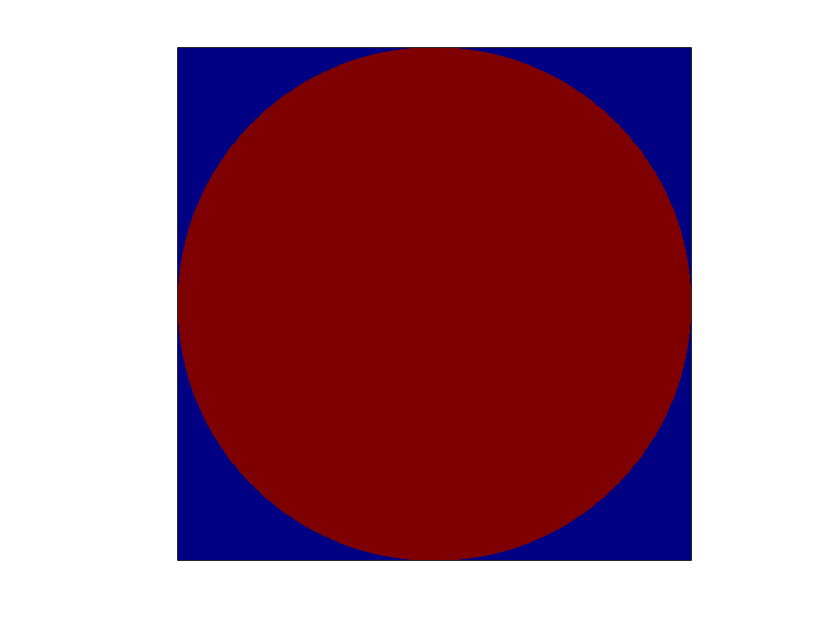

RmnC = 1

rhoExp = 1

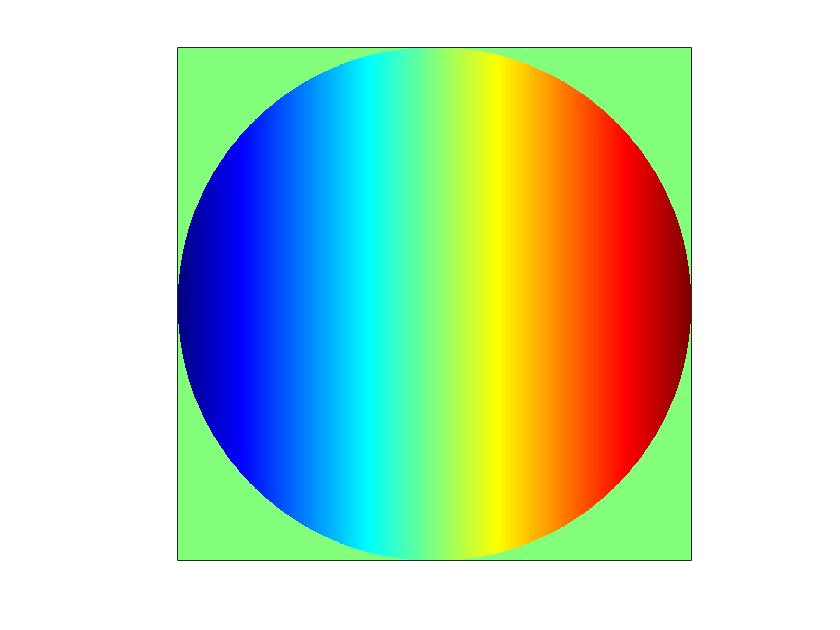

RmnC = 1

rhoExp = 1

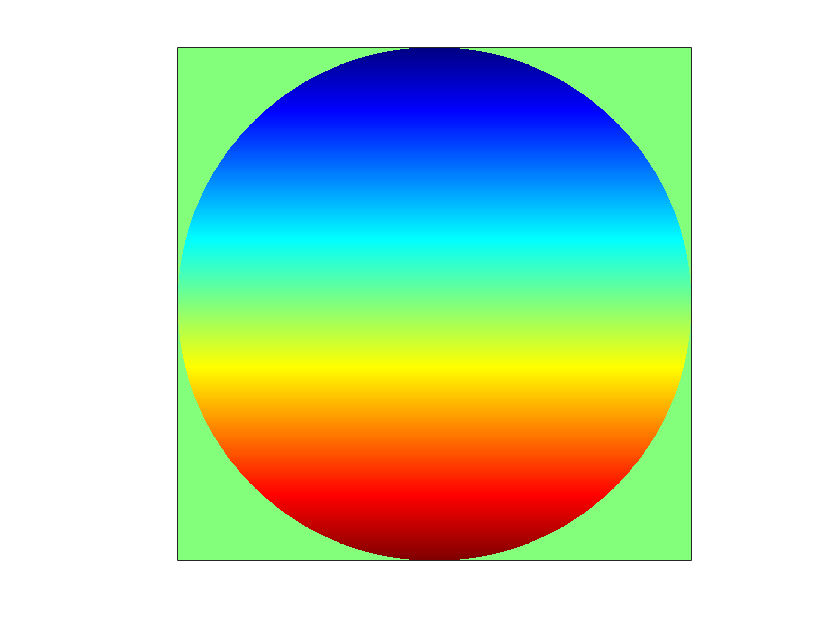

RmnC =      2    -1


rhoExp =      2     0


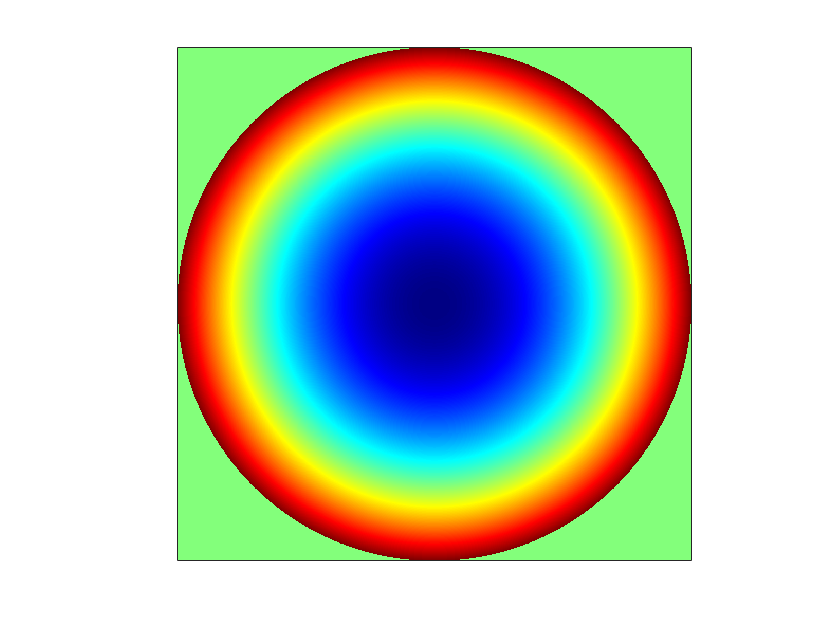

RmnC = 1

rhoExp = 2

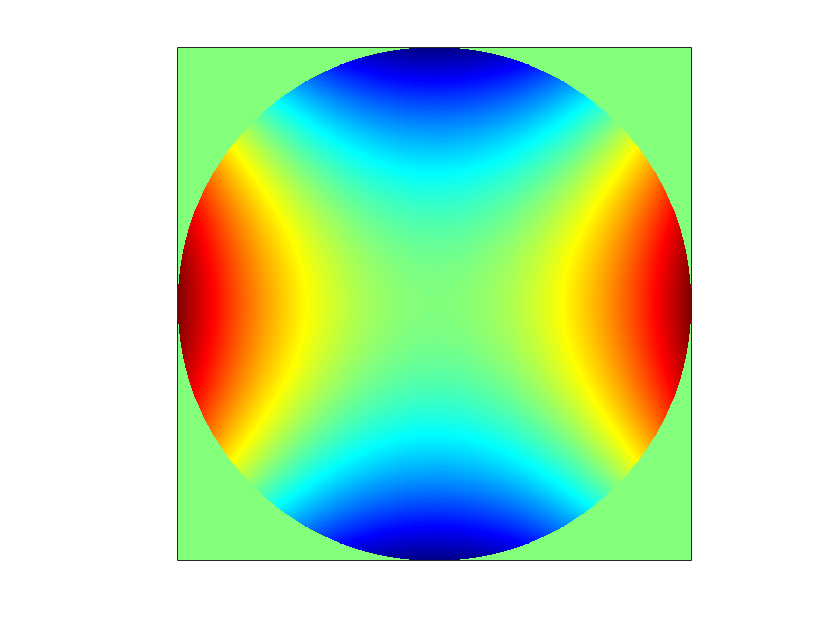

RmnC = 1

rhoExp = 2

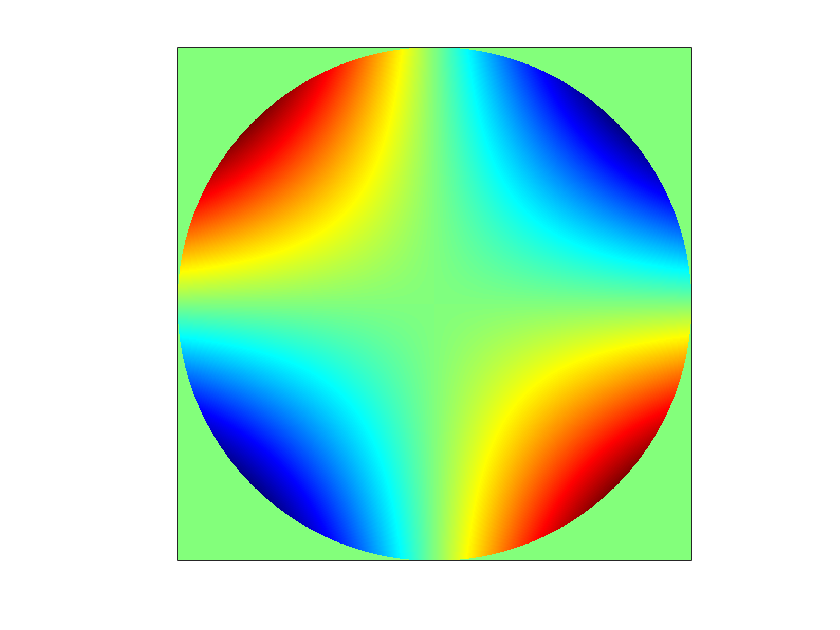

RmnC =      3    -2


rhoExp =      3     1


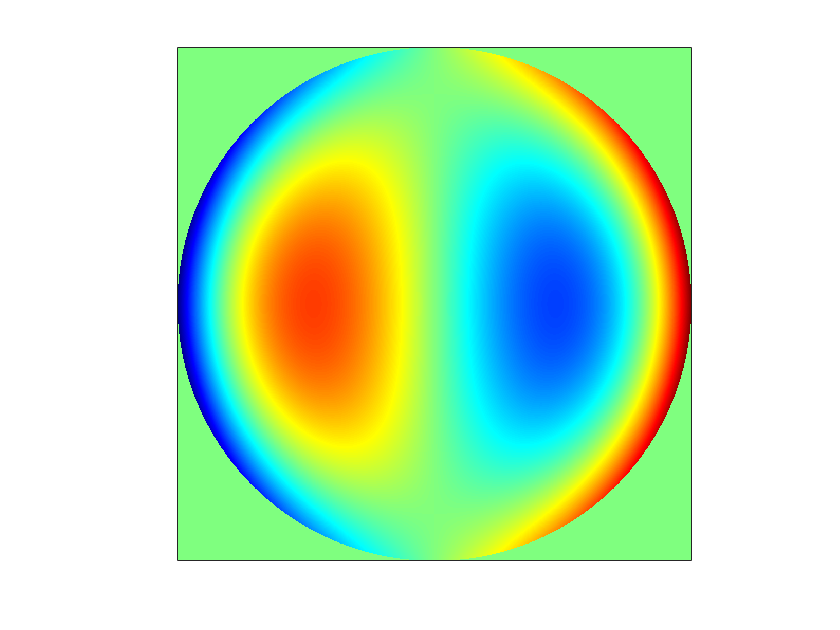

RmnC =      3    -2


rhoExp =      3     1


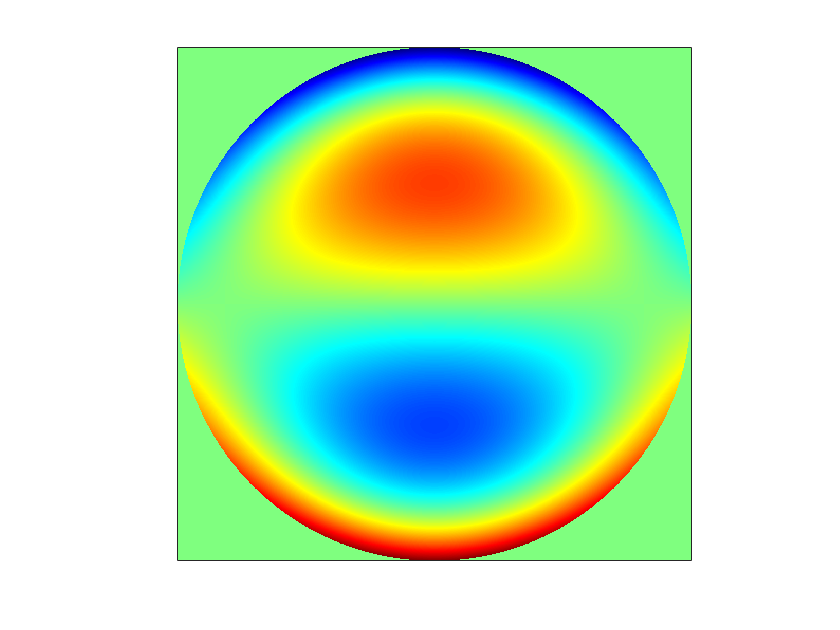

RmnC = 1

rhoExp = 3

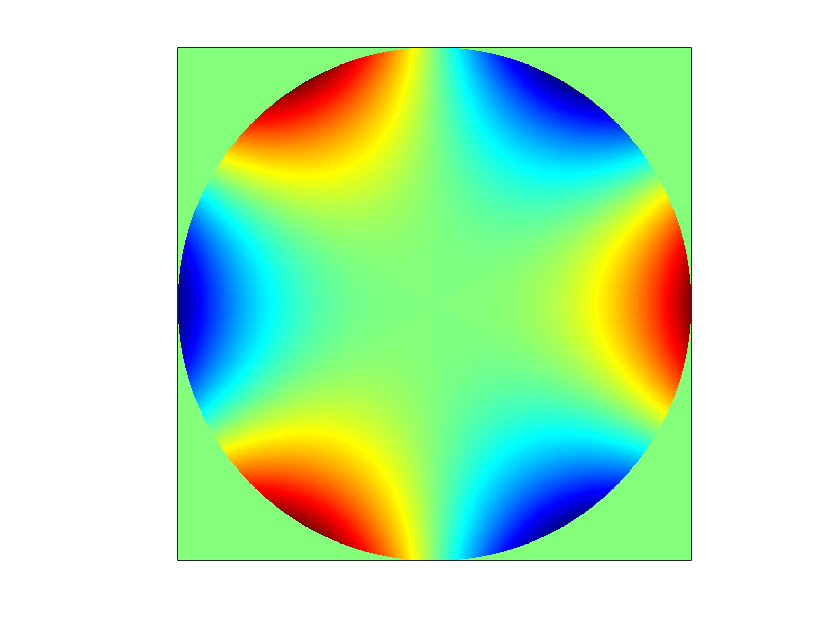

RmnC = 1

rhoExp = 3

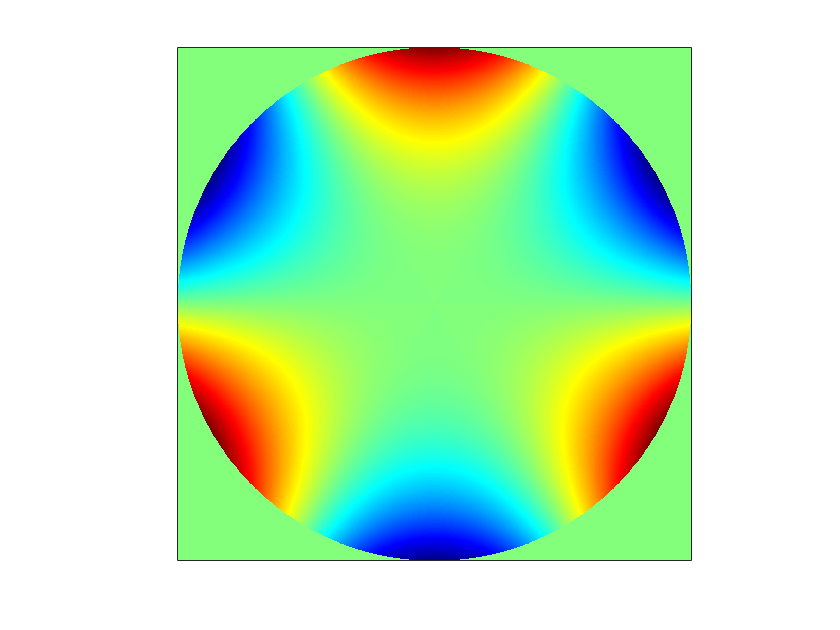

RmnC =      6    -6     1


rhoExp =      4     2     0


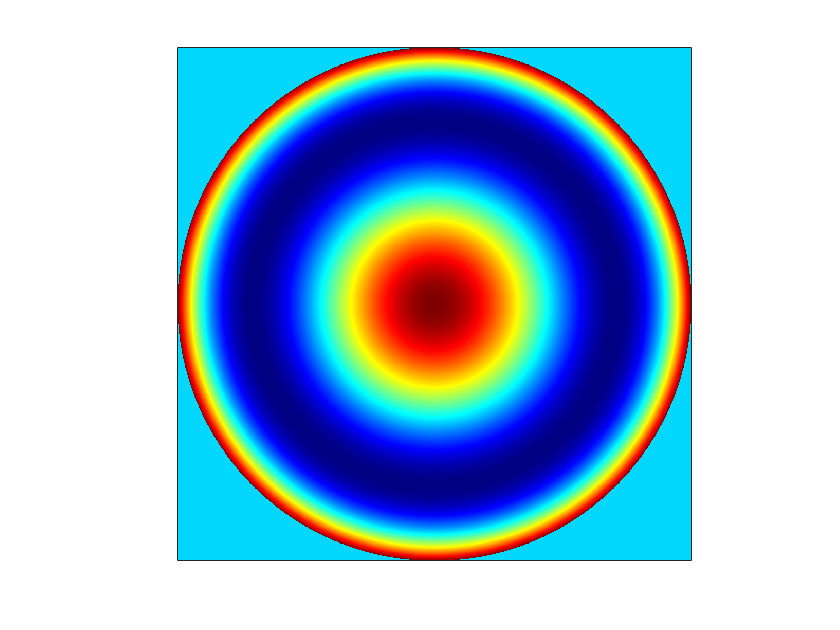


%Zernike Tilt
Tilt = true;
if Tilt
    m(3) = -1;
    n(3) = 1;
end

%Zernike Defocus
Defocus = true;
if Defocus
    m(4) = 0;
    n(4) = 2;
end

%Zernike Astigmatism
Astigmatism_0 = true;
if Astigmatism_0
    m(5) = 2;
    n(5) = 2;
end

%Zernike Astigmatism
Astigmatism_45 = true;
if Astigmatism_45
    m(6) = -2;
    n(6) = 2;
end

%Zernike Coma_X
Coma_X = true;
if Coma_X
    m(7) = 1;
    n(7) = 3;
end

%Zernike Coma_Y
Coma_Y = true;
if Coma_Y
    m(8) = -1;
    n(8) = 3;
end

%Zernike Trefoil X
Trefoil_X = true;
if Trefoil_X
    m(9) = 3;
    n(9) = 3;
end

%Zernike Trefoil Y
Trefoil_Y = true;
if Trefoil_Y
    m(10) = -3;
    n(10) = 3;
end

%Zernike Spherical
Spherical = true;
if Spherical
    m(11) = 0;
    n(11) = 4;
end

list = [Piston,Tilt,Tip,Defocus,Astigmatism_0,Astigmatism_45,Coma_X,Coma_Y,Trefoil_X,Trefoil_Y,Spherical];

for i=1:length(list)
    if list(i) == true
        [RmnC,rhoExp] = calcPoly(abs(m(i)),n(i))
        myData = calcShape(RmnC,rhoExp,m(i),n(i),Pixel);
        f = figure(i);
        set(gcf,'color','w');
        imagesc(myData);
        set(gca,'XTick',[], 'YTick', [])
        axis square;
        colormap(jet);
        fname = ['Zernike' num2str(i) '.eps'];
        exportgraphics(f,fname,"ContentType","vector","BackgroundColor","none")
    end
end